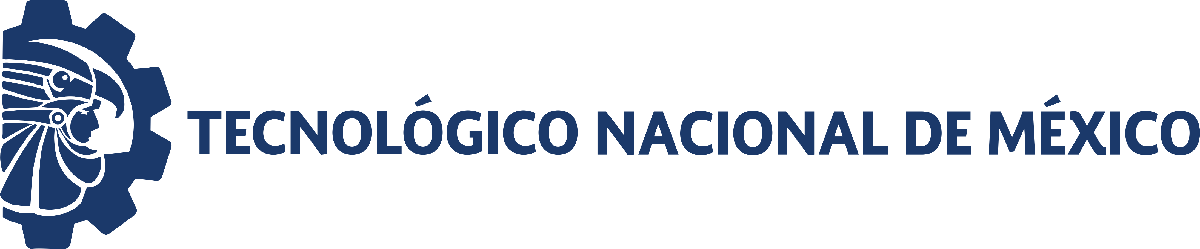                                 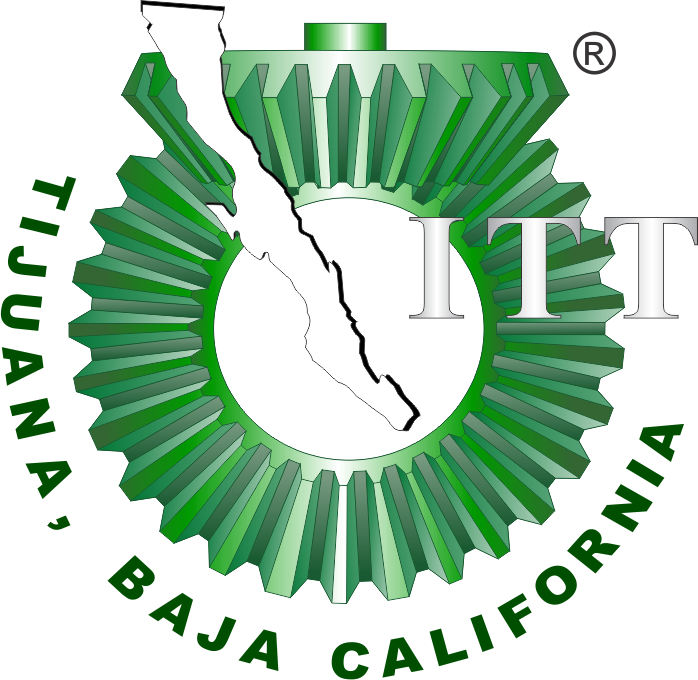

# Práctica cero: Mecánica pulmonar

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información generalhttps:

[Foto]

Nombre del alumno: **Diego David Villaseñor Lopez**

Número de control: **22210431**

Correo institucional:** L22210431@tectijuana.edu.mx**

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

clc; clear; close all; warning('off','all')
tend= '10';
file= 'sysp0';
open_system(file);
parameters.StopTime= tend;
parameters.Solver = 'ode45';
parameters.MaxStep = '1E-3';
Controlador= 'PID';

## Respuesta al escalón

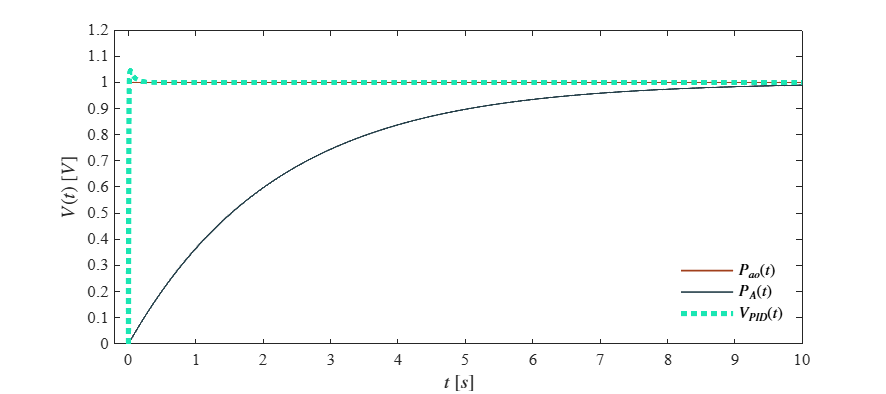

Signal = 'Escalon';
set_param('sysp0/S1','sw','1');
set_param('sysp0/Pao(t)','sw','1');
x1 = sim(file,parameters);
plotsignals(x1.t,x1.Pao,x1.PA,x1.VPID,Signal)

## Respuesta al impulso

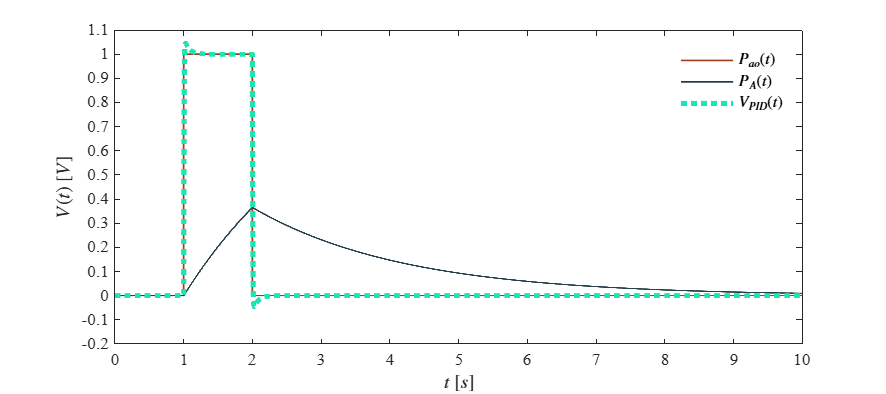

Signal = 'Impulso';
set_param('sysp0/S1','sw','0');
set_param('sysp0/Pao(t)','sw','1');
x2 = sim(file,parameters);
plotsignals(x2.t,x2.Pao,x2.PA,x2.VPID,Signal)

## Respuesta a la rampa

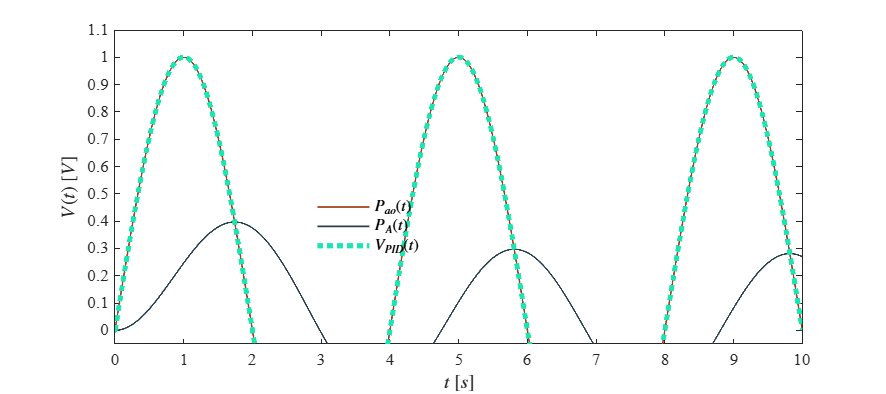

Signal = 'Rampa';
set_param('sysp0/S1','sw','0');
set_param('sysp0/Pao(t)','sw','0');
x3 = sim(file,parameters);
plotsignals(x3.t,x3.Pao,x3.PA,x3.VPID,Signal)

## Respuesta a la función sinusoidal

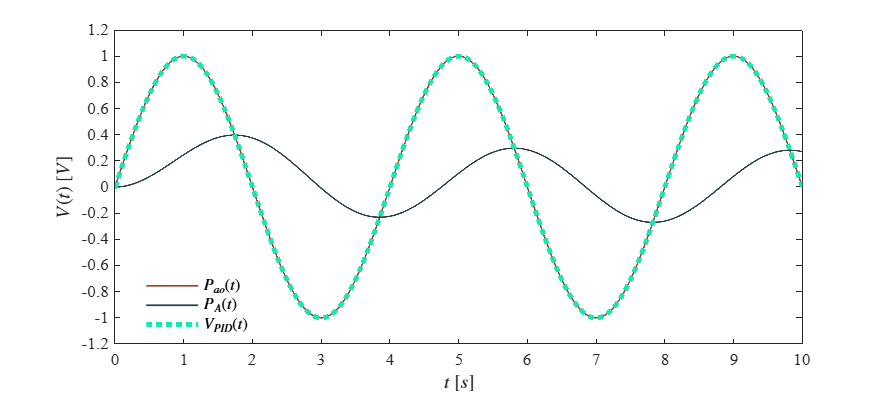

Signal = 'Sinusoidal';
set_param('sysp0/S1','sw','1');
set_param('sysp0/Pao(t)','sw','0');
x4 = sim(file,parameters);
plotsignals(x4.t,x4.Pao,x4.PA,x4.VPID,Signal)

**Funcion : Respuesta a las señales**

function plotsignals (t,Ve,Vs,VPID,Signal)
    set(figure(),'Color','w')
    set(gcf,'units','Centimeters','Position',[1,1,18,8])
    set(gca,'FontName','Times New Roman')
    fontsize(10,'points')
    %Color 1 naranja [0.15,0.25,0.29]
    %Color 2 morado [0.5,0.3,0.2]
    %Color 3 azul [0.63,0.25,0.11]
    %Color 4 rojo [0.1,0.9,0.7]
    na1 =  [0.15,0.25,0.29];
    mor1 =[0.5,0.3,0.2];
    azu1 = [0.63,0.25,0.11];
    roj1 = [0.1,0.9,0.7];
    hold on ; grid off; box on

    plot(t,Ve,'LineWidth',1,'Color',azu1)
    plot(t,Vs,'LineWidth',1,'Color',na1)
    plot(t,VPID,':','LineWidth',3,'Color',roj1)

    xlabel('$t$ $[s]$','Interpreter','Latex')
    ylabel('$V(t)$ $[V]$','Interpreter','Latex')

    L = legend('$P_{ao}(t)$','$P_A(t)$','$V_{PID}(t)$');
    set(L,'Interpreter','Latex','Location','Best','Box','Off')

    if Signal == "Escalon"
        xlim([-0.2,10]); xticks (0:1:10)
        ylim([0,1.2]); yticks (0:0.1:1.2)
    elseif Signal == "Impulso"
        xlim([0,10]); xticks (0:1:10)
        ylim([-0.2,1.1]); yticks (-0.2:0.1:1.1)
    elseif Signal == "Rampa"
        xlim([0,10]); xticks (0:1:10)
        ylim([-0.05,1.1]); yticks (0:0.1:1.1)
    elseif Signal == "Sinusoidal"
        xlim([0,10]); xticks (0:1:10)
        ylim([-1.2,1.2]); yticks (-1.2:0.2:1.2)
    end
    exportgraphics(gcf,[Signal,'.pdf'],'ContentType','Vector')
end
